# this code is to draw thecorrelation map of different TR moments

clc
clear

addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))
% rmpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\MCXStudio'))
% rmpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
% addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\MCXStudio'))
addpath(genpath('F:\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
addpath(genpath('F:\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))

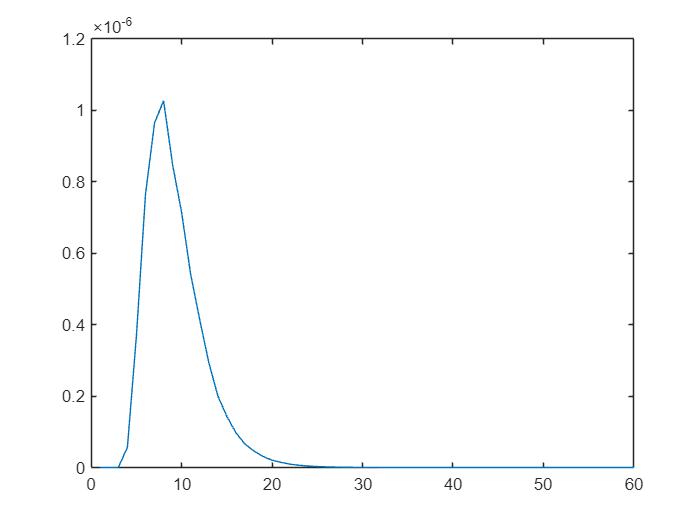

% input tpsf and Jacobians should be the normalized tpsf
close all

%-----------data normalization------------
h = 6.626e-34; % Planck constant in Js
lambda = 800e-9; % wavelength in m
c = 299792453;
sp_eng = h.*c/(lambda); % single photon energy
% bandwidth = 1/exposure_time/2;
mpe = 3e-3; % w/mm^2
rep_rate = 300e6; % repetetion rate Hz 300M
single_pulse_energy = mpe./rep_rate; % J/mm^2
single_pulse_photon_count = single_pulse_energy./sp_eng;
exposure_time_tr = 1; % unit in second, the exposure time for the TCSPC
BinFlag = ((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2; % the bin value of each timebin
DCR = 100; % dark count rate 100/s
TCPSC_lim = 0.01*300e6;
% sensitive area is set to be 1mm^2
%-----------data normalization------------

% tumour_pos_range = [20:5:40 41 45:5:54 54];
tumour_pos_range = [20:5:40 45:5:54 54];

n = numel(tumour_pos_range);
metrics = {'m0','m1','m2','v','fullTPSF','earlyGate','lateGate'};

opt_FI = struct(); opt_D = struct();
for k = 1:numel(metrics)
    opt_FI.(metrics{k}) = zeros(n,1);
    opt_D.(metrics{k})  = zeros(n,1);
end

FI = struct(); D = struct();
for k = 1:numel(metrics)
    FI.(metrics{k}) = zeros(numel(SD_dist),1);
end

depth_index = 1;

% tumour_pos = 10; % debug

% % ------------figures for ploting--------------
% for k = 1:numel(metrics)
%     f(k) = figure('Name',metrics{k}, 'NumberTitle','off');
% end
% % ------------figures for ploting--------------

% tumour_pos = 20;  % debug
for tumour_pos = 20
    % % % % ----------update tumour mask -------------------
    tuct_pos1 = [tumour_pos 0];
    tuCt = [center_pos(1)-tuct_pos1(1) center_pos(2)+tuct_pos1(2)];
    tuR1 = 15;
    D2Cu = sqrt((grid_z-tuCt(1)).^2+(grid_y-tuCt(2)).^2);
    tumour_mask_it = zeros(2*brain_radius,2*brain_radius);
    for i = 1:size(tumour_mask_it,1)
        for j = 1:size(tumour_mask_it,2)
            if D2Cu(i,j)<=tuR1
                tumour_mask_it(i, j) = 1;
            end
        end
    end
    tumour_mask_it = rot90(tumour_mask_it);
    % figure;imagesc(tumour_mask_it);
    % imagesc(squeeze(log10(abs(sum(jacobians(:,:,:,1),3)))))
    % % % % ----------update tumour mask -------------------

    % data_load = load(sprintf("tpsfs_jacobians_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("tpsfs_jacobians_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("data3/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    data_load = load(sprintf("data5/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));

    %------------ normalize 3-----------make sure the highest count rate
    % % matches the TCSPC standard
    % data_load.tpsfs = data_load.tpsfs./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    % data_load.jacobians =  data_load.jacobians./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    tpsf_normalized = data_load.tpsfs./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    Jacobians_norm = data_load.jacobians./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;

    % sd_ind = 100; % debug
    for sd_ind = 52 % starting from 52 to get rid of sampling noise
        tpsf_sd =  data_load.tpsfs(:,sd_ind);
        Jacobian_sd = squeeze(data_load.jacobians(:,:,:,sd_ind));
    end

end

plot(tpsf_sd)

## generate random Poisson data and moments

%---------normalize tpsf for generating Poisson---------
tpsf_nonzero = tpsf_sd(find(tpsf_sd~=0));
tpsf_nonzero_index = find(tpsf_sd~=0);
tpsf_poisson_norm = zeros(size(tpsf_nonzero));
tpsf_poisson_norm(tpsf_nonzero_index) = tpsf_nonzero./min(tpsf_nonzero);
tpsf_poisson_norm = round(tpsf_poisson_norm);
%---------normalize tpsf for generating Poisson---------

rnd_num = 1e6;
lambda_rep = repmat(tpsf_poisson_norm',[rnd_num,1]);
obs = poissrnd(lambda_rep,rnd_num,length(tpsf_poisson_norm)); 


mome_m0 = sum(obs,2);
mome_m1 = sum(BinFlag'.*obs,2)./sum(obs,2);
mome_m2 = sum(BinFlag'.^2.*obs,2)./sum(obs,2);
mome_v = mome_m2-mome_m1.^2;


c1 = [1, 1, 1];   % 浅蓝
c2 = [0.5, 0.5, 0.9];   % 深蓝

n = 256;  % 渐变级数
% 对 RGB 三通道分别做线性插值
r = linspace(c1(1), c2(1), n)';
g = linspace(c1(2), c2(2), n)';
b = linspace(c1(3), c2(3), n)';
blueMap = [r, g, b];

## m0-m1

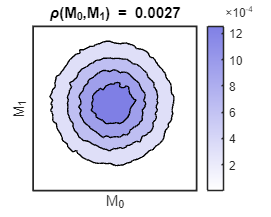


% 1) 先做 2D 直方统计
nbins = 100;
[Ncount, edgesX, edgesY] = histcounts2(mome_m0, mome_m1, nbins);
[grid_ey,grid_ex] = ndgrid(edgesY(1:nbins),edgesX(1:nbins));


% --------------------Desired sizes (cm)
figW = 17.2/3;   % figure width
figH = 17.2/3*0.8;    % figure height
axW  = figW - 2*0.282;   % axes width
axH  = figH - 4*0.282;    % axes height
axLeft = 2 * 0.282;  % left margin (from figure left edge)
axBottom = 2 * 0.282; % bottom margin

% -----------------Create the figure at the given size
fig1 = figure;
ax1 = axes('Parent',fig1);

set(fig1, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax1, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig


% 3) 绘制等高线
% contourf(ax1,grid_ex( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     grid_ey( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     Ncount( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4)))./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

contourf(ax1,grid_ex(26:75,26:75), ...
    grid_ey(26:75,26:75), ...
    Ncount( 26:75,26-3:75-3)./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

colormap(blueMap)
colorbar
xlabel('M_0');
ylabel('M_1');
title(sprintf('\\rho(M_{0},M_{1}) = %.4f',corr(mome_m0,mome_m1)),'Interpreter','tex');
axis square

ax1.XTick = [];      % 清空 X 轴刻度位置
ax1.YTick = [];      % 清空 Y 轴刻度位置
ax1.XTickLabel = {}; % 清空 X 轴刻度标签
ax1.YTickLabel = {}; % 清空 Y 轴刻度标签
ax1.LineWidth   = 1;             % axes box thickness
ax1.FontName    = 'Arial';
ax1.FontSize    = 8;            % journal‐style font size

print(fig1, 'F6-1.png', '-dpng', '-r1200');

## m0-m2

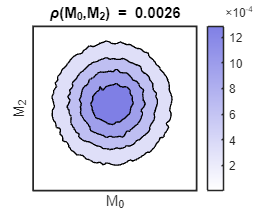

% 1) 先做 2D 直方统计
nbins = 100;
[Ncount, edgesX, edgesY] = histcounts2(mome_m0, mome_m2, nbins);
[grid_ey,grid_ex] = ndgrid(edgesY(1:nbins),edgesX(1:nbins));


% --------------------Desired sizes (cm)
figW = 17.2/3;   % figure width
figH = 17.2/3*0.8;    % figure height
axW  = figW - 2*0.282;   % axes width
axH  = figH - 4*0.282;    % axes height
axLeft = 2 * 0.282;  % left margin (from figure left edge)
axBottom = 2 * 0.282; % bottom margin

% -----------------Create the figure at the given size
fig2 = figure;
ax2 = axes('Parent',fig2);

set(fig2, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax2, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig


% 3) 绘制等高线
% contourf(ax1,grid_ex( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     grid_ey( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     Ncount( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4)))./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

contourf(ax2,grid_ex(26:75,26:75), ...
    grid_ey(26:75,26:75), ...
    Ncount( 26:75,26-3:75-3)./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

colormap(blueMap)
colorbar
xlabel('M_0');
ylabel('M_2');
title(sprintf('\\rho(M_{0},M_{2}) = %.4f',corr(mome_m0,mome_m2)),'Interpreter','tex');
axis square

ax2.XTick = [];      % 清空 X 轴刻度位置
ax2.YTick = [];      % 清空 Y 轴刻度位置
ax2.XTickLabel = {}; % 清空 X 轴刻度标签
ax2.YTickLabel = {}; % 清空 Y 轴刻度标签
ax2.LineWidth   = 1;             % axes box thickness
ax2.FontName    = 'Arial';
ax2.FontSize    = 8;            % journal‐style font size

print(fig2, 'F6-2.png', '-dpng', '-r1200');

## m0-v

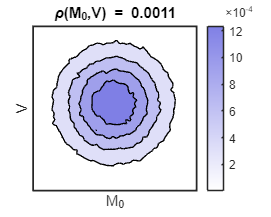

% 1) 先做 2D 直方统计
nbins = 100;
[Ncount, edgesX, edgesY] = histcounts2(mome_m0, mome_v, nbins);
[grid_ey,grid_ex] = ndgrid(edgesY(1:nbins),edgesX(1:nbins));


% --------------------Desired sizes (cm)
figW = 17.2/3;   % figure width
figH = 17.2/3*0.8;    % figure height
axW  = figW - 2*0.282;   % axes width
axH  = figH - 4*0.282;    % axes height
axLeft = 2 * 0.282;  % left margin (from figure left edge)
axBottom = 2 * 0.282; % bottom margin

% -----------------Create the figure at the given size
fig3 = figure;
ax3 = axes('Parent',fig3);

set(fig3, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax3, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig


% 3) 绘制等高线
% contourf(ax1,grid_ex( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     grid_ey( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     Ncount( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4)))./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

contourf(ax3,grid_ex(26:75,26:75), ...
    grid_ey(26:75,26:75), ...
    Ncount( 26:75,26:75)./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

colormap(blueMap)
colorbar
xlabel('M_0');
ylabel('V');
title(sprintf('\\rho(M_{0},V) = %.4f',corr(mome_m0,mome_v)),'Interpreter','tex');
axis square

ax3.XTick = [];      % 清空 X 轴刻度位置
ax3.YTick = [];      % 清空 Y 轴刻度位置
ax3.XTickLabel = {}; % 清空 X 轴刻度标签
ax3.YTickLabel = {}; % 清空 Y 轴刻度标签
ax3.LineWidth   = 1;             % axes box thickness
ax3.FontName    = 'Arial';
ax3.FontSize    = 8;            % journal‐style font size

print(fig3, 'F6-3.png', '-dpng', '-r1200');

## M1-m2

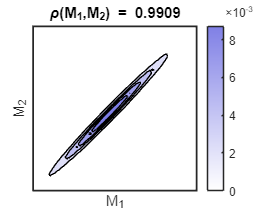

% 1) 先做 2D 直方统计
nbins = 100;
[Ncount, edgesX, edgesY] = histcounts2(mome_m1, mome_m2, nbins);
[grid_ey,grid_ex] = ndgrid(edgesY(1:nbins),edgesX(1:nbins));


% --------------------Desired sizes (cm)
figW = 17.2/3;   % figure width
figH = 17.2/3*0.8;    % figure height
axW  = figW - 2*0.282;   % axes width
axH  = figH - 4*0.282;    % axes height
axLeft = 2 * 0.282;  % left margin (from figure left edge)
axBottom = 2 * 0.282; % bottom margin

% -----------------Create the figure at the given size
fig4 = figure;
ax4 = axes('Parent',fig4);

set(fig4, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax4, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig


% 3) 绘制等高线
% contourf(ax1,grid_ex( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     grid_ey( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     Ncount( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4)))./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

contourf(ax4,grid_ex(26:75,26:75), ...
    grid_ey(26:75,26:75), ...
    Ncount( 26-2:75-2,26-2:75-2)./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

colormap(blueMap)
colorbar
xlabel('M_1');
ylabel('M_2');
title(sprintf('\\rho(M_{1},M_{2}) = %.4f',corr(mome_m1,mome_m2)),'Interpreter','tex');
axis square

ax4.XTick = [];      % 清空 X 轴刻度位置
ax4.YTick = [];      % 清空 Y 轴刻度位置
ax4.XTickLabel = {}; % 清空 X 轴刻度标签
ax4.YTickLabel = {}; % 清空 Y 轴刻度标签
ax4.LineWidth   = 1;             % axes box thickness
ax4.FontName    = 'Arial';
ax4.FontSize    = 8;            % journal‐style font size

print(fig4, 'F6-4.png', '-dpng', '-r1200');

## M1 -v

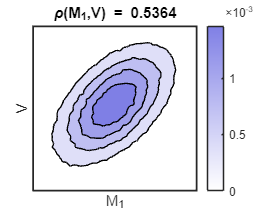

% 1) 先做 2D 直方统计
nbins = 100;
[Ncount, edgesX, edgesY] = histcounts2(mome_m1, mome_v, nbins);
[grid_ey,grid_ex] = ndgrid(edgesY(1:nbins),edgesX(1:nbins));


% --------------------Desired sizes (cm)
figW = 17.2/3;   % figure width
figH = 17.2/3*0.8;    % figure height
axW  = figW - 2*0.282;   % axes width
axH  = figH - 4*0.282;    % axes height
axLeft = 2 * 0.282;  % left margin (from figure left edge)
axBottom = 2 * 0.282; % bottom margin

% -----------------Create the figure at the given size
fig5 = figure;
ax5 = axes('Parent',fig5);

set(fig5, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax5, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig


% 3) 绘制等高线
% contourf(ax1,grid_ex( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     grid_ey( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     Ncount( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4)))./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

contourf(ax5,grid_ex(26:75,26:75), ...
    grid_ey(26:75,26:75), ...
    Ncount( 26-5:75-5,26:75)./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

colormap(blueMap)
colorbar
xlabel('M_1');
ylabel('V');
title(sprintf('\\rho(M_{1},V) = %.4f',corr(mome_m1,mome_v)),'Interpreter','tex');
axis square

ax5.XTick = [];      % 清空 X 轴刻度位置
ax5.YTick = [];      % 清空 Y 轴刻度位置
ax5.XTickLabel = {}; % 清空 X 轴刻度标签
ax5.YTickLabel = {}; % 清空 Y 轴刻度标签
ax5.LineWidth   = 1;             % axes box thickness
ax5.FontName    = 'Arial';
ax5.FontSize    = 8;            % journal‐style font size

print(fig5, 'F6-5.png', '-dpng', '-r1200');

## m2-v

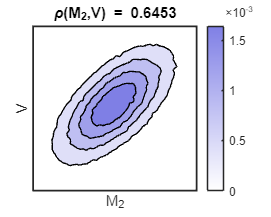


% 1) 先做 2D 直方统计
nbins = 100;
[Ncount, edgesX, edgesY] = histcounts2(mome_m2, mome_v, nbins);
[grid_ey,grid_ex] = ndgrid(edgesY(1:nbins),edgesX(1:nbins));


% --------------------Desired sizes (cm)
figW = 17.2/3;   % figure width
figH = 17.2/3*0.8;    % figure height
axW  = figW - 2*0.282;   % axes width
axH  = figH - 4*0.282;    % axes height
axLeft = 2 * 0.282;  % left margin (from figure left edge)
axBottom = 2 * 0.282; % bottom margin

% -----------------Create the figure at the given size
fig6 = figure;
ax6 = axes('Parent',fig6);

set(fig6, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax6, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig


% 3) 绘制等高线
% contourf(ax1,grid_ex( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     grid_ey( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4))), ...
%     Ncount( round(nbins/4)-1:(nbins-round(nbins/4)),round(nbins/4)+1:(nbins-round(nbins/4)))./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

contourf(ax6,grid_ex(26:75,26:75), ...
    grid_ey(26:75,26:75), ...
    Ncount( 26-5:75-5,26:75)./rnd_num, 4, 'LineColor','k');  % 填充等高线，15 条

colormap(blueMap)
colorbar
xlabel('M_2');
ylabel('V');
title(sprintf('\\rho(M_{2},V) = %.4f',corr(mome_m2,mome_v)),'Interpreter','tex');
axis square

ax6.XTick = [];      % 清空 X 轴刻度位置
ax6.YTick = [];      % 清空 Y 轴刻度位置
ax6.XTickLabel = {}; % 清空 X 轴刻度标签
ax6.YTickLabel = {}; % 清空 Y 轴刻度标签
ax6.LineWidth   = 1;             % axes box thickness
ax6.FontName    = 'Arial';
ax6.FontSize    = 8;            % journal‐style font size

print(fig6, 'F6-6.png', '-dpng', '-r1200');